# Surface plot visualisation

prompt = "Please enter the path to image data you want to visualise.";
filename = input(prompt, "s");
%filename = "E:\Padova\Thesis\themoonrocks\Images\mi_map_03_n27e308n26e309sc.img";
global patchSize
global currentCombination
global chnr

currentCombination = [1, 2, 10];
chnr = length(currentCombination);

patchSize = 2048;

Use1 = readPatch(filename);
% Use3 = readPatchWithProcessing(filename);
% img1 = Use1(:,:,2);
% img3 = Use3(:,:,2);
mySurface = Use1(:,:,1);

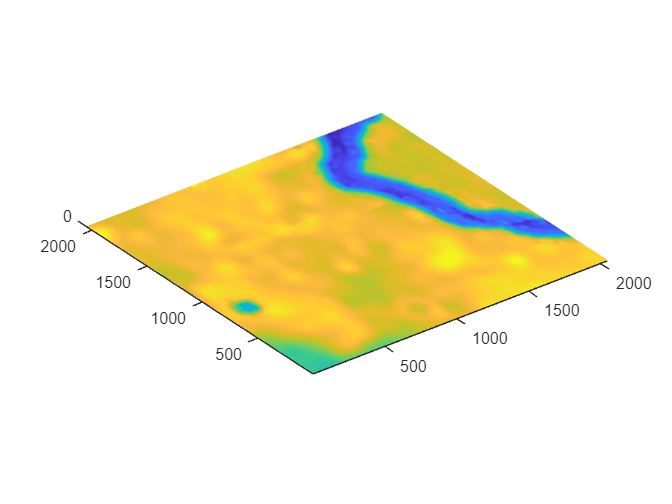

posSurface = (mySurface-min(mySurface(:)));
scaledSurface = posSurface/max(posSurface(:));
%surf(1:2048,1:2048,posSurface);
%surf(1:2048,1:2048,mySurface,posSurface*255);
% surf(1:2048,1:2048,mySurface,[posSurface*255 posSurface*255 posSurface*255]);
% surf(1:2048,1:2048,posSurface);

[X,Y] = meshgrid(1:patchSize,1:patchSize);
% surf(X,Y,posSurface);
surf(X,Y,posSurface,EdgeColor='none');
axis equal

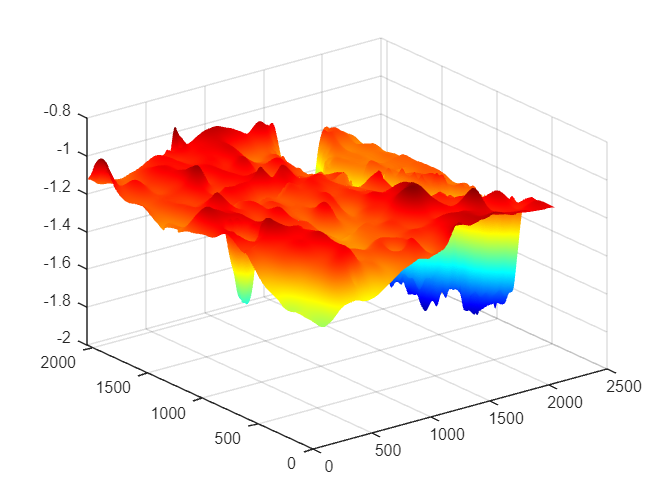

surf(X,Y,mySurface,posSurface,EdgeColor='none');
colormap jet

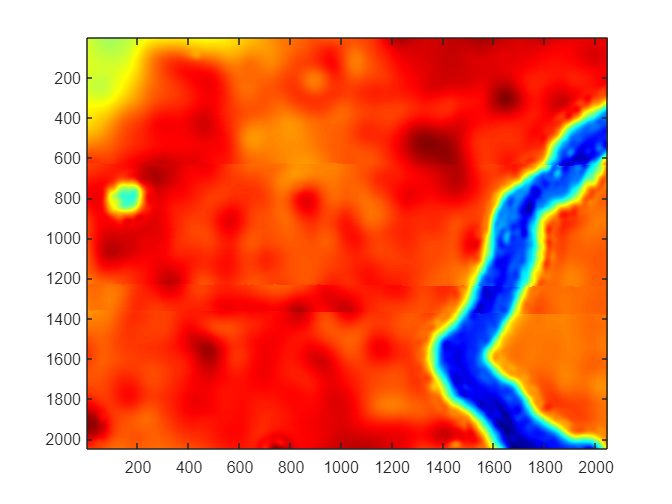

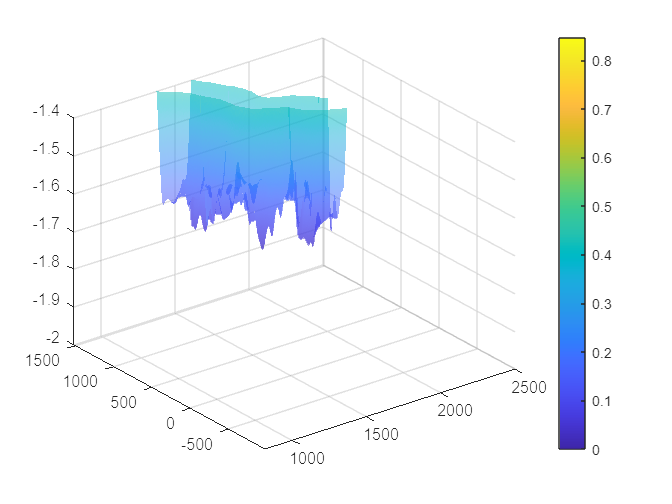

imagesc(mySurface)